data = load("C:\Users\alex\OneDrive - California Institute of Technology\Documents\Graduate\Research\2D-dispersion-GPR\OUTPUT\FOR COVAR EXPER output 07-Dec-2020 15-37-06\DATA N_struct188 RNG_offset0 07-Dec-2020 15-37-06.mat",'EIGENVALUE_DATA','WAVEVECTOR_DATA','CONSTITUTIVE_DATA');

EIGENVALUE_DATA = data.EIGENVALUE_DATA;
WAVEVECTOR_DATA = data.WAVEVECTOR_DATA;

[N_wv,N_eig,N_struct] = size(EIGENVALUE_DATA);

Cs = cov4D(WAVEVECTOR_DATA,EIGENVALUE_DATA);

eig_idx = 1;

% fig = figure2();
% ax = axes(fig);
[M,N,~,~] = size(Cs{eig_idx})

M = 11

N = 11

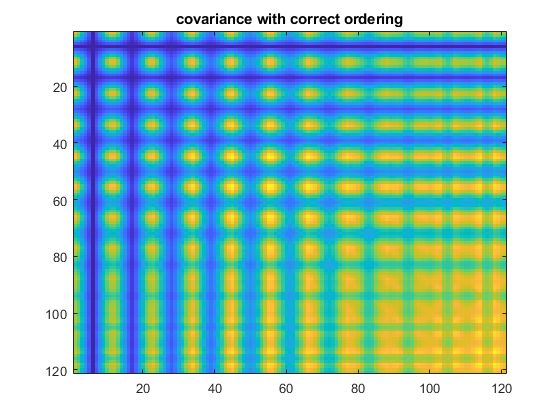

C = reshape(Cs{eig_idx},M^2,N^2);
imagesc(C)
title('covariance with correct ordering')


size(EIGENVALUE_DATA)

ans =    121     8   188


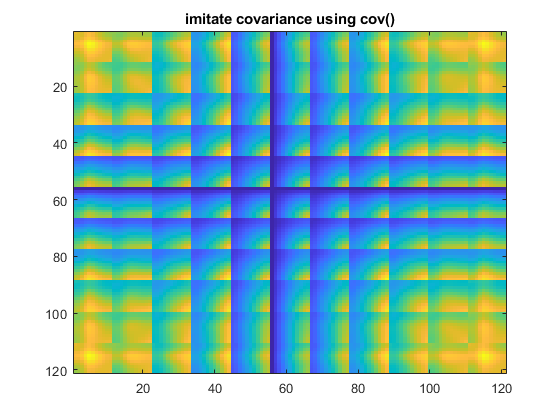


C_imitate = cov(squeeze(EIGENVALUE_DATA(:,eig_idx,:))');

imagesc(C_imitate)
title('imitate covariance using cov()')

^wrong!


wv = WAVEVECTOR_DATA(:,:,1)

wv =    -3.1416         0
   -3.1416    0.3142
   -3.1416    0.6283
   -3.1416    0.9425
   -3.1416    1.2566
   -3.1416    1.5708
   -3.1416    1.8850
   -3.1416    2.1991
   -3.1416    2.5133
   -3.1416    2.8274


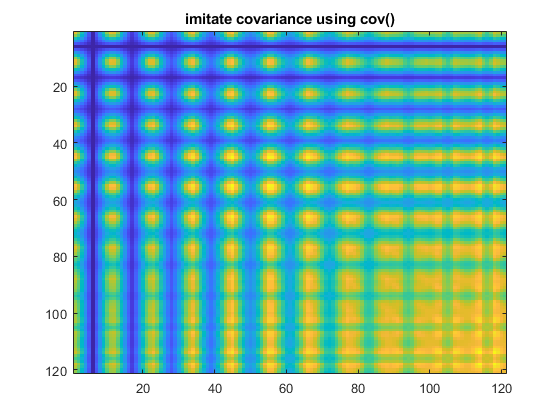

[~,idxs] = sort(wv(:,2));

WAVEVECTOR_DATA = WAVEVECTOR_DATA(idxs,:,:);
EIGENVALUE_DATA = EIGENVALUE_DATA(idxs,:,:);

C_imitate = cov(squeeze(EIGENVALUE_DATA(:,eig_idx,:))');

imagesc(C_imitate)
title('imitate covariance using cov()')